# 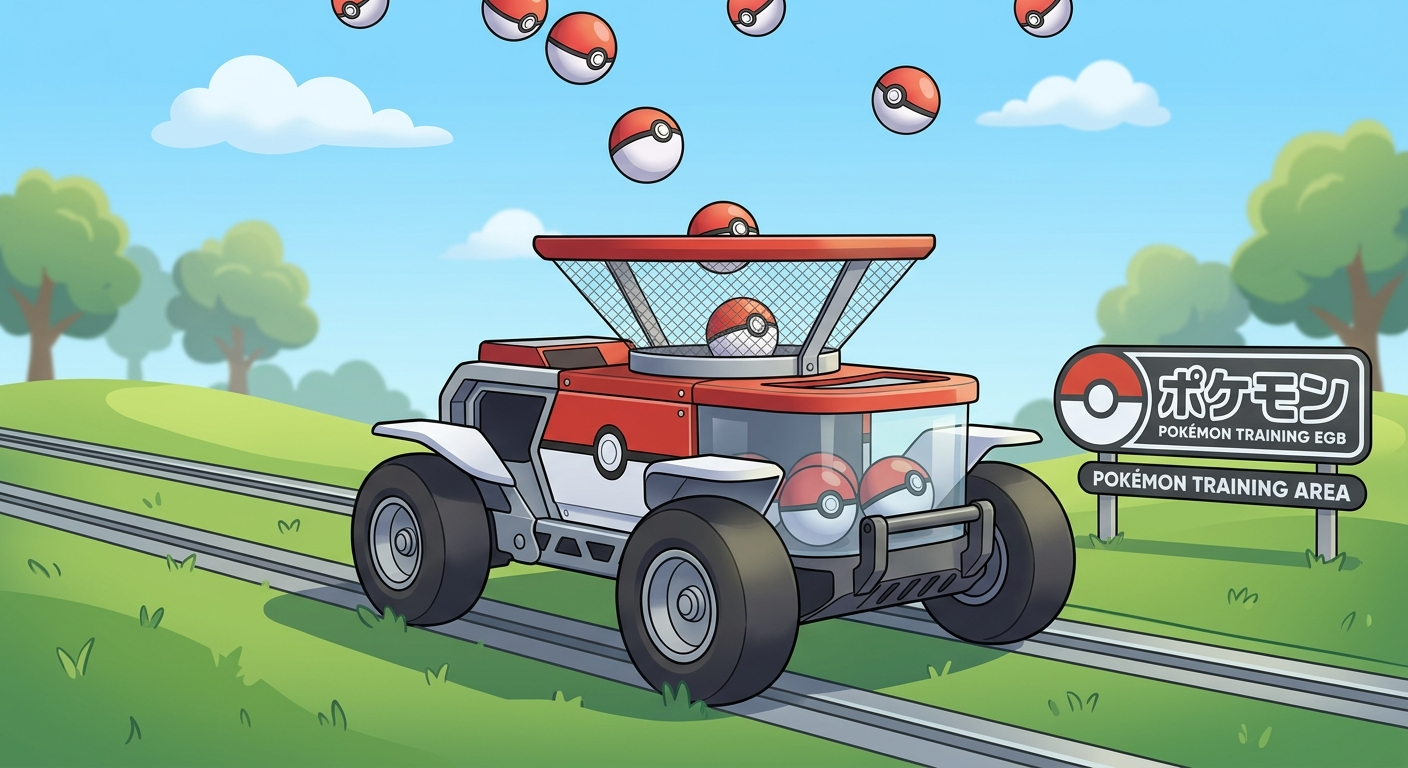

# **Project: Gotta Catch 'Em All!**

## **Project Overview**

You are tasked with designing a position controller for a cart moving along a track. The cart can effectively go backwards and forwards along the track and is responsible for catching Poke Balls that fall from the sky (you can imagine that junior Pokemon trainers do not have very good aim when trying to catch their Pokemon!). The Poke Balls fall from the sky at a fixed height of $h=2.5$ metres above ground and new Poke Balls are released as soon as the previous Poke Ball reaches the ground (or equivalently is caught by the cart). The Poke Balls are always dropped with zero initial velocity and accelerate downwards at $g=9.81$ m/s$^2$. Because of the haphazard aim of the trainers, Pokemon Balls fall from anywhere within the positional region of $x^\ast\in[-1.5,1.5]$ metres at random. Pokemon trainers are each given 20 Poke Balls and it is the job of your automated cart to catch all the balls before they hit the ground. Every Poke Ball that is caught results in a point, with the maximum score being 20. Additionally, the cart should never exit the region of $x\in[-2,2]$ metres, as the track is not maintained very well in this region. If the cart does exit the region, a *Penalty *is noted. The final score that you will receive is given by


$$Score = \#Catches-\#Penalties.$$


You are able to make the cart move forwards and backwards by applying a voltage to the motors driving the wheels. This applied voltage therefore serves as the input signal, $u(t)$, to the system. Notably, the maximum voltage that can be applied to the cart is $u_{max}=50$ Volts. This is important, as it means that you cannot make your cart go infinitely fast.

The simulation runs in `MATLAB` and is initialised by running the Cart Simulator section in this live script. An example of the simulation is shown in Figure 1.

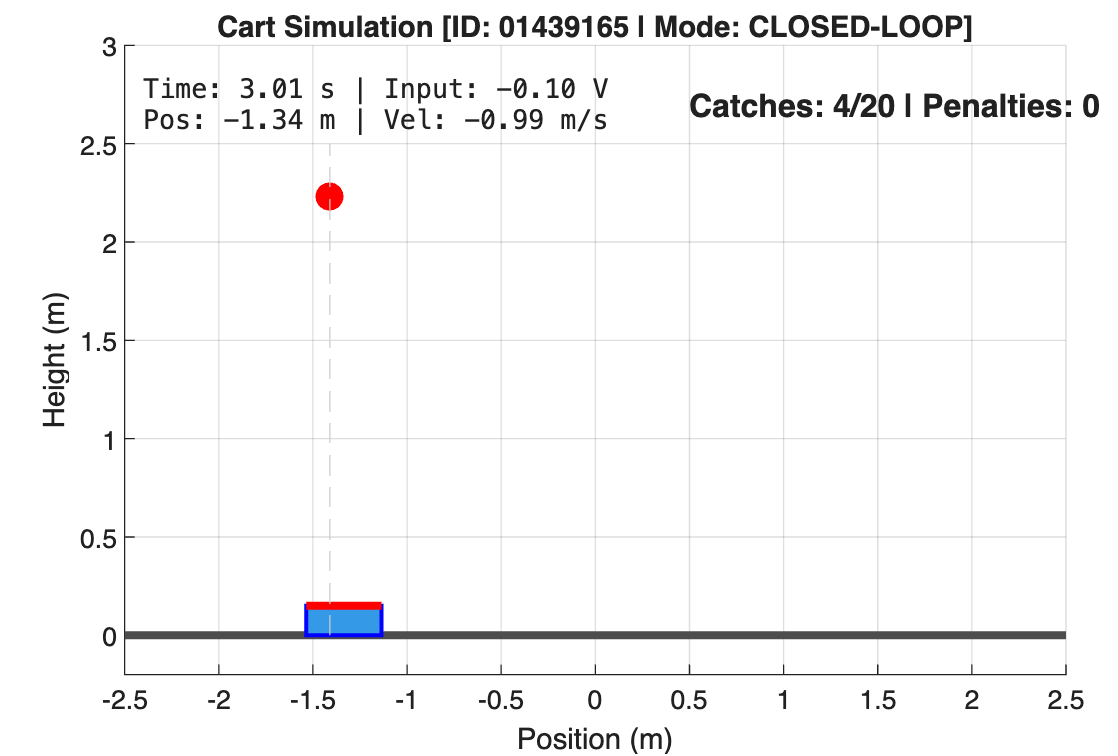

**Figure 1**: Image of cart simulation.

While in operation, the pop-up window showing the animation of the cart will indicate your number of catches and penalties, as well as other information such as the time and velocity. 

Before running the simulation, you will be required to enter your PeopleSoft ID. It is important that you enter your correct ID, as every student will receive a different plant for their cart depending on their ID, which you will be marked against. As such, it is unlikely that a control solution for one student will transfer nicely to that of another student.

In order to solve this problem suitably, you will be required to complete four subsequent parts:

- **Part 1**: System Identification (8 marks)

- **Part 2**: Determining Closed-Loop Specifications (5 marks)

- **Part 3**: Control Design (7 marks)

- **Part 4**: Implementation (5 marks)

The maximum mark obtainable for the project is therefore 25 marks. More information above each part is provided further below.

## Format

You will be providing all your answers within this live script and then submitting the live script in Amathuba. You will typically be expected to answer the questions below using a combination of text and images. This will be made clear to you for each question. It is strongly recommended that you type out your text answers directly, as required. You can also take pictures of your written work and paste them in the relevant spaces, such as if you have a diagram that is not easily made in MATLAB. 

You can enter the math-mode within live scripts by using the $ signs framed on either side of the equation you want to render. For example, $f=ma$ is generated when typing

You can also edit the LateX equations by double-clicking on the equation after it has been rendered.

Note that you will not be awarded additional marks for waffling in your answers. Instead, please try to be as succinct as possible when providing written responses. Less is more!

Very important: all figures that you paste below should have a title that indicates your PeopleSoft ID. This can be done using the line of code below after the command to plot the figure.

## Part 1: System Identification (8 marks)

The first step of this Project is to find a suitable model of your open-loop cart. Specifically, you will need to identify $P(s)$. This can be achieved using methods taught in **Chapter 6**. The Cart Simulator has two modes: *open-loop *and *closed-loop*. In *open-loop* mode, you can choose a signal to inject into the cart in order to perform system characterisation of the cart. 

All relevant data from the cart, such as position, velocity, and input against time, is logged and viewable within this script within the Post-Simulation Analysis section. The data should then be used to form a canonical model of your open-loop system. Once you have arrived at a model, you should then simulate the model's response to the same input signal that you injected into the cart in order to assure yourself that both the model and cart simulation have the same output response.

#### **Task 1:** Determine an appropriate estimate of the open-loop cart system with position as the output and the applied voltage as the input.

*Format: Your answer must be provided below in this section with brief explanation of your decisions and should also include all relevant figures related to how you obtained the necessary parameters, and how you verified your result. You can use code blocks to generate figures, but your final figures should be pasted into the space below.*

%Code block to assist with generating figures and performing calculations. 
% All figures generated using this code block should be pasted above as part of the answer.


## Part 2: Determining Closed-Loop Specifications (5 marks)

The second part of the Project requires you to determine appropriate closed-loop specifications for your cart given the information above. The specifications will ultimately lead you to performing a frequency-domain design using log-polar plots. As such, you will need to develop a suitable reference model, followed by the associated *stay-above *and *stay-below *boundaries that shape your loop transfer function. The procedure as detailed in **Chapter 11** should be followed. Note that given the limit on the voltage that can be applied to the cart, you should not overdo it on the specifications. Instead, find the least taxing specifications (in terms of input action) that would maximise your score.

#### **Task 2:** Using the information provided, determine a suitable settling time, percentage overshoot, and steady-state error requirement for the cart system such that your *Score *can be maximised.

*Format: Your answer must be provided below in this section with explanation of your decisions and should also include all relevant figures (if applicable) related to how you obtained your answer. You can use code blocks to generate figures, but your final figures should be pasted into the space below.*

%Code block to assist with generating figures and performing calculations. 
% All figures generated using this code block should be pasted above as part of the answer.


## Part 3: Control Design (7 marks)

With **Part 1** and **Part 2** completed, the next step is to design an appropriate feedback controller to meet the closed-loop specifications. The feedback controller will be implemented such that 

$T(s)=\frac{P(s)G(s)}{1+P(s)G(s)}$.

This means that your feedback controller should be designed appropriately based on the theory (and code) provided in **Chapter 12**. Note that at this stage of the project you are not required to apply your controller to the cart simulation. Instead, you should be designing your controller, $G(s)$, and then assessing its performance based on your modelled $P(s)$ from **Part 1**.

#### **Task 3:** Using the plant model from Part 1 and the desired specifications in Part 2, determine the log-polar design boundaries and synthesize an admissible feedback controller. The control design should make use of frequency-domain design based in log-polar plots and a brief explanation of the decisions made should be indicated in the space below. Once the feedback controller has been designed, a unit step response (using the `step` function) of the closed-loop system should be provided to demonstrate the closed-loop system's adherence to the specifications. 

*Format: Your answer must be provided below in this section with explanation of your decisions and should also include all relevant figures related to how you designed your controller, and how you verified your result. You can use code blocks to generate figures, but your final figures should be pasted into the space below.*

%Code block to assist with generating figures and performing calculations. 
% All figures generated using this code block should be pasted above as part of the answer.



## Part 4: Implementation (5 marks)

Following completion of **Part 1 **to **Part 3**, you can now test out your feedback control solution on the cart simulator. The score is automatically tallied based on number of catches subtracted by the number of penalties you incur, and your final mark for **Part 4** is equal to your score divided by 4, with 5 being the maximum obtainable mark.

In order for the cart simulator to make use of your controller, you must define your designed $G(s)$ within the **Closed-Loop Configuration (Control Design Mode) **code block. The *closed-loop* mode must also be selected for this part. The feedback is already baked into the simulator such that the applied voltage sent to the cart will be governed by


$$U(s)=G(s)[R(s)-Y(s)],$$


where $R(s)$ is the reference position for the current falling ball and $Y(s)$ is the measured cart position.

#### **Task 4:** Apply your designed controller to the cart simulator with the aim of maximising your score.

*Format: Provide a screenshot of the resulting score and mark below when the simulation completes. You are not required to provide any other detail for this part.*

## Cart Simulator

Running this section begins the cart simulator. Note that you first need to enter your PeopleSoft ID and that the simulation mode must be set appropriately.

%Clears all variables and closes all windows before the simulation begins.
clear; clc; close all;

### Student Identification

Enter your 8-digit PeopleSoft ID before running this section.

peoplesoft_id = ;

### Simulation Mode

Mode options: 

- *open-loop* - Apply custom voltage signal to identify plant dynamics 

- *closed-loop* - Test feedback controller against 20-drop benchmark

Select *open-loop *when completing the system identification stage. Select *closed-loop *when testing your feedback controller.

SIM_MODE = "open-loop"    ;

### Open-Loop Configuration (System ID Mode)

This code runs when *open-loop* mode is selected.

if strcmpi(SIM_MODE, 'open-loop')
    % Define custom input voltage u(t) as a function handle @(t)
    
    mag = 1; %Magnitude of input signal
    u_func = @(t) mag*sin(t)
    t_final = 6; % Total simulation duration (s)
    
    % Run simulation
    clf
    sim_data = run_cart_simulation(peoplesoft_id,'open-loop', u_func, t_final);

### Closed-Loop Configuration (Control Design Mode)

This code runs when *closed-loop* mode is selected.

elseif strcmpi(SIM_MODE, 'closed-loop')
    % Define Laplace variable s using Control System Toolbox
    s = tf('s');
    
    % -------------------------------------------------------------------
    % PLACE YOUR CONTROLLER HERE
    G = 1; %Temporary, not-so-great controller that you should be replacing!
    
    % Run 20-ball drop benchmark simulation
    clf
    sim_data = run_cart_simulation(peoplesoft_id,'closed-loop', G);
end

### Post-Simulation Analysis

This code should be run after the simulation completes.

figure('Name', 'Simulation Results', 'Color', 'w');

subplot(3, 1, 1);
plot(sim_data.t, sim_data.x, 'b', 'LineWidth', 1.5); hold on;
plot(sim_data.t, sim_data.x_target, 'r--', 'LineWidth', 1.2);
ylabel('Position (m)');
title('Cart Position vs Target');
legend('Cart Position', 'Target Position', 'Location', 'best');
grid on;

subplot(3, 1, 2);
plot(sim_data.t, sim_data.v, 'm', 'LineWidth', 1.5);
ylabel('Velocity (m/s)');
title('Cart Velocity');
grid on;

subplot(3, 1, 3);
plot(sim_data.t, sim_data.u, 'k', 'LineWidth', 1.5);
ylabel('Control Voltage (V)');
xlabel('Time (s)');
title('Motor Input Voltage');
axis tight
grid on;